stopType = 'step';

%Function and derivatives 
F.f = @(x) 100.*(x(2) - x(1)^2).^2 + (1 - x(1)).^2;
F.df = @(x) [-400*(x(2) - x(1)^2)*x(1) - 2*(1 - x(1)); 
              200*(x(2) - x(1)^2)];  % gradient handler, 2-dim vector
F.d2f = @(x) [-400*(x(2) - 3*x(1)^2) + 2, -400*x(1); -400*x(1), 200]; % hessian handler, 2-dim vector

%Initialisation 
alpha0 = 1;
maxIter = 50;
alpha_max = alpha0;
tol = 1e-6;

x0 = [1.2; 1.2];

%Initialisation of the algorithm 
nIter = 0;
x_k = x0;
info.xs = x0;
info.alphas = alpha0;
stopCond = false; 
alpha_max = alpha0;

%Initialise backtracking line search 
opts.rho = 0.1;
opts.c1 = 1e-4;
alpha = alpha0;

%Newton Method 
while (~stopCond && nIter <= maxIter) % StopCond = true and nIter is less than or equal
    
    % ======================  ===================================
    % x_k - current iteration point (stopping condition)
    % x_k_1 - the previous iteration point (stopping condition)
    direction = -(inv(F.d2f(x_k)))*F.df(x_k)
    %Backtracking line search for alpha
    while F.f(x_k+alpha*direction) > F.f(x_k)+(opts.c1*alpha)*dot(F.df(x_k),direction)
        alpha = alpha*opts.rho
    end
    x_next = x_k + alpha.*direction
    info.alphas(end+1) = alpha
    info.xs(1,end+1) = x_next(1)
    info.xs(2,end) = x_next(2)
    x_k_1 = x_k
    x_k = x_next
    nIter = nIter + 1
    alpha = alpha0
        switch stopType
      case 'step' 
        % Compute relative step length
        normStep = norm(x_k - x_k_1)/norm(x_k_1);
        stopCond = (normStep < tol);
      case 'grad'
        stopCond = (norm(F.df(x_k), 'inf') < tol*(1 + tol*abs(F.f(x_k))));
    end
    
end

direction =    -0.0041
    0.2302


x_next =     1.1959
    1.4302


info = struct with fields:
        xs: [2×1 double]
    alphas: [1 1]


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 1]


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 1]


x_k_1 =     1.2000
    1.2000


x_k =     1.1959
    1.4302


nIter = 1

alpha = 1

direction =    -0.1953
   -0.4670


alpha = 0.1000

x_next =     1.1764
    1.3835


info = struct with fields:
        xs: [2×2 double]
    alphas: [1 1 0.1000]


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 1 0.1000]


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 1 0.1000]


x_k_1 =     1.1959
    1.4302


x_k =     1.1764
    1.3835


nIter = 2

alpha = 1

direction =    -0.1634
   -0.3841


alpha = 0.1000

x_next =     1.1600
    1.3451


info = struct with fields:
        xs: [2×3 double]
    alphas: [1 1 0.1000 0.1000]


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 1 0.1000 0.1000]


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 1 0.1000 0.1000]


x_k_1 =     1.1764
    1.3835


x_k =     1.1600
    1.3451


nIter = 3

alpha = 1

direction =    -0.1423
   -0.3295


alpha = 0.1000

x_next =     1.1458
    1.3121


info = struct with fields:
        xs: [2×4 double]
    alphas: [1 1 0.1000 0.1000 0.1000]


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 1 0.1000 0.1000 0.1000]


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 1 0.1000 0.1000 0.1000]


x_k_1 =     1.1600
    1.3451


x_k =     1.1458
    1.3121


nIter = 4

alpha = 1

direction =    -0.1265
   -0.2891


alpha = 0.1000

x_next =     1.1332
    1.2832


info = struct with fields:
        xs: [2×5 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000]


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000]


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000]


x_k_1 =     1.1458
    1.3121


x_k =     1.1332
    1.2832


nIter = 5

alpha = 1

direction =    -0.1139
   -0.2572


x_next =     1.0193
    1.0260


info = struct with fields:
        xs: [2×6 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1]


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1]


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1]


x_k_1 =     1.1332
    1.2832


x_k =     1.0193
    1.0260


nIter = 6

alpha = 1

direction =    -0.0054
    0.0020


x_next =     1.0139
    1.0280


info = struct with fields:
        xs: [2×7 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1]


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1]


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1]


x_k_1 =     1.0193
    1.0260


x_k =     1.0139
    1.0280


nIter = 7

alpha = 1

direction =    -0.0138
   -0.0281


x_next =     1.0001
    1.0000


info = struct with fields:
        xs: [2×8 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1]


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1]


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1]


x_k_1 =     1.0139
    1.0280


x_k =     1.0001
    1.0000


nIter = 8

alpha = 1

direction = 	1.0e+-4 *

   -0.7696
    0.3786


x_next =     1.0000
    1.0000


info = struct with fields:
        xs: [2×9 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1]


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1]


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1]


x_k_1 =     1.0001
    1.0000


x_k =     1.0000
    1.0000


nIter = 9

alpha = 1

direction = 	1.0e+-5 *

   -0.2952
   -0.5899


x_next =     1.0000
    1.0000


info = struct with fields:
        xs: [2×10 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1]


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1]


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1]


x_k_1 =     1.0000
    1.0000


x_k =     1.0000
    1.0000


nIter = 10

alpha = 1

direction = 	1.0e+-11 *

   -0.3498
    0.1721


x_next =      1
     1


info = struct with fields:
        xs: [2×11 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1 1]


info = struct with fields:
        xs: [2×12 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1 1]


info = struct with fields:
        xs: [2×12 double]
    alphas: [1 1 0.1000 0.1000 0.1000 0.1000 1 1 1 1 1 1]


x_k_1 =     1.0000
    1.0000


x_k =      1
     1


nIter = 11

alpha = 1


% Assign output values 
xMin = x_k;
fMin = F.f(x_k); 

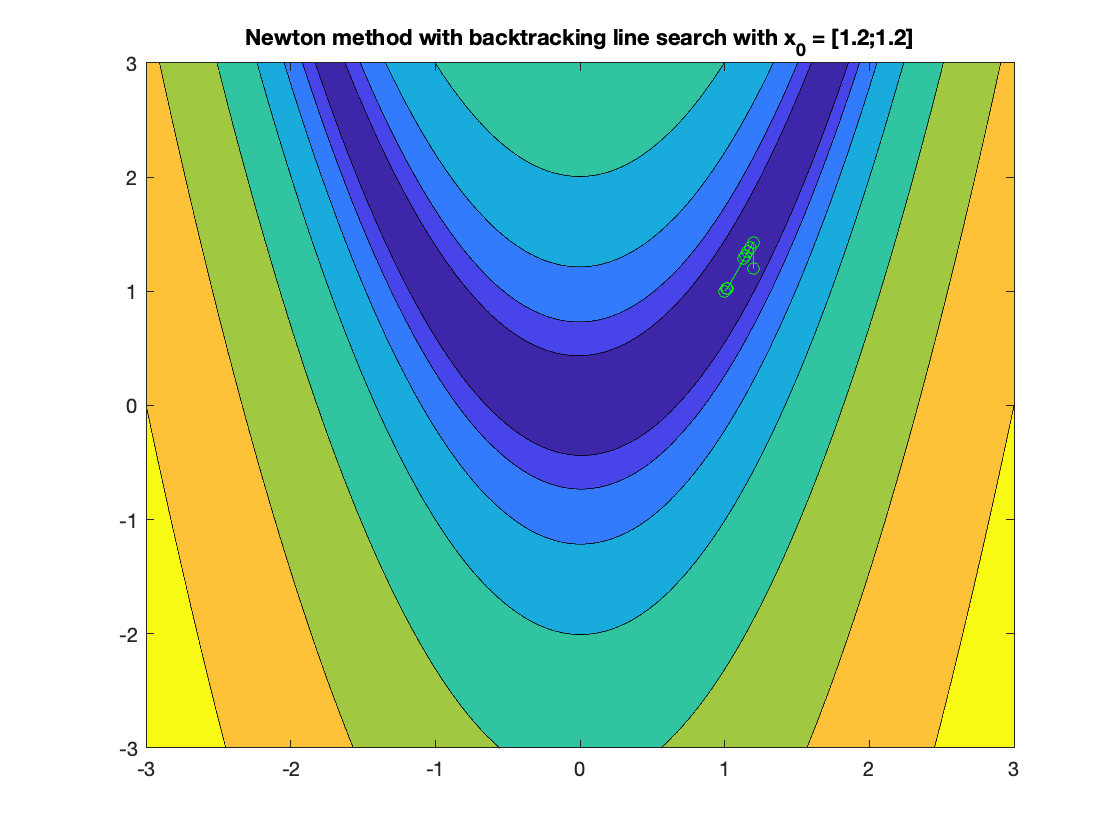

%Plotting the trajectories on the contours
f1 = @(x,y) 100.*(y - x.^2).^2 + (1 - x).^2;
n = 1000;
x = linspace(-1.5,1.5,1000);
h = 2/n;
y = x;
[X,Y] = meshgrid(x,y);
beta = 2;

figure, contourf(beta*X, beta*Y, log(max(f1(beta*X,beta*Y),10))); hold on
plot(info.xs(1,:), info.xs(2,:), 'og-')
title('Newton method with backtracking line search with x_0 = [1.2;1.2]')

lambdas = eig(F.d2f(xMin)).';
lambdas

lambdas = 	1.0e+03 *

    0.0004    1.0016


p = 1; 
% convergance rate
conSteep = convergenceHistory(info, info.xs(:,end), F, 2)

conSteep = struct with fields:
     x: [0.2828 0.4727 0.4221 0.3804 0.3445 0.3130 0.0324 0.0313 8.6072e-05 6.5965e-06 3.8983e-12 0]
     f: [5.8000 0.0384 0.0311 0.0257 0.0213 0.0178 0.0172 1.9411e-04 3.6852e-06 8.7202e-12 7.6101e-21 0]
    df: [125.1693 0.3998 0.5451 0.6222 0.6597 0.6722 5.9229 0.0400 0.0859 8.3586e-06 3.9044e-09 0]


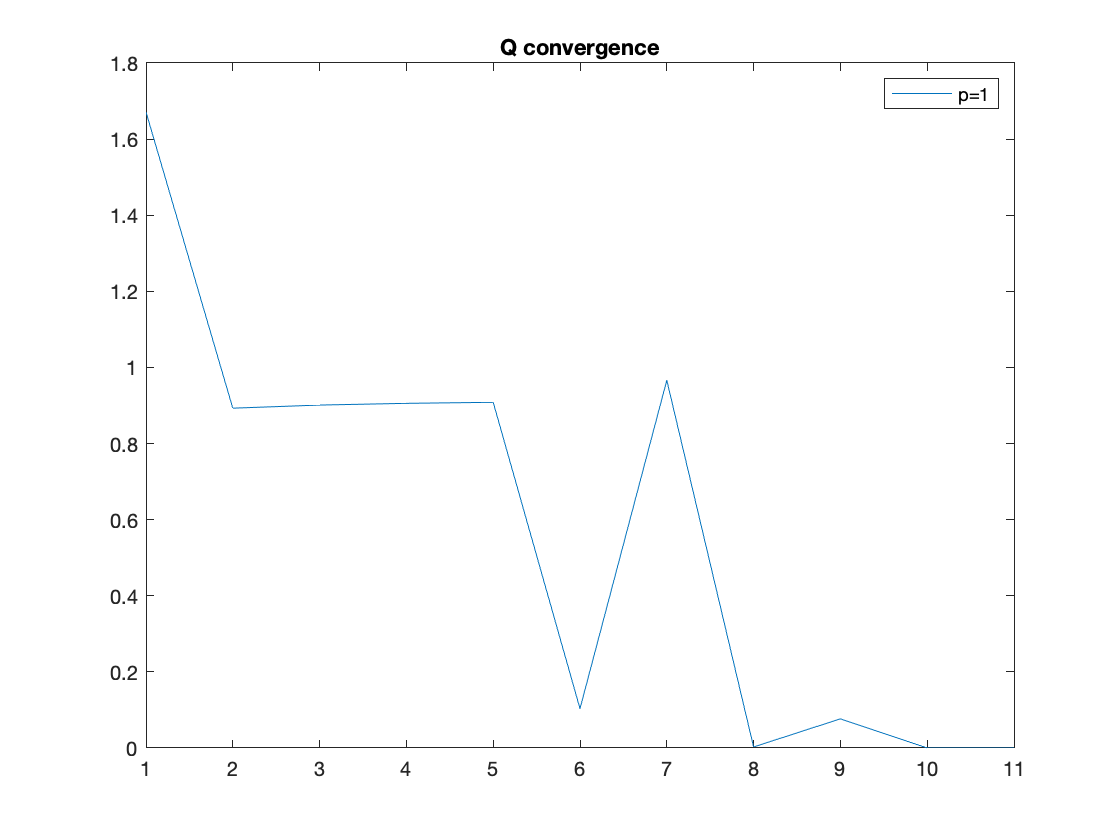

rs1 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
ps=1.4; rss = conSteep.x(2:end)./(conSteep.x(1:end-1).^ps); 
p=2; rs2 = conSteep.x(2:end)./(conSteep.x(1:end-1).^p); 
figure, plot(rs1); hold on; title('Q convergence'); legend('p=1')
saveas(gcf, 'newton_conv_4b', 'png')

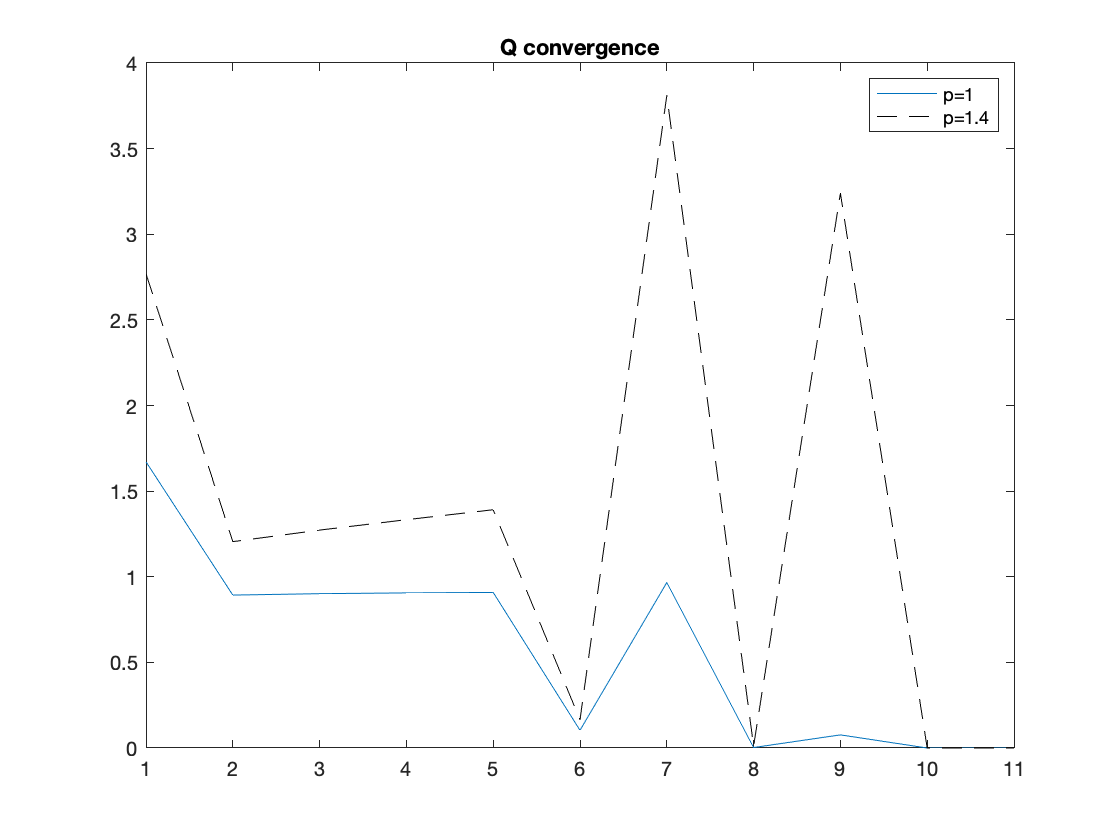

figure, plot(rs1); hold on; plot(rss,'k--'); title('Q convergence'); legend('p=1',['p=' num2str(ps)])
saveas(gcf, 'newton_conv_4b2', 'png')

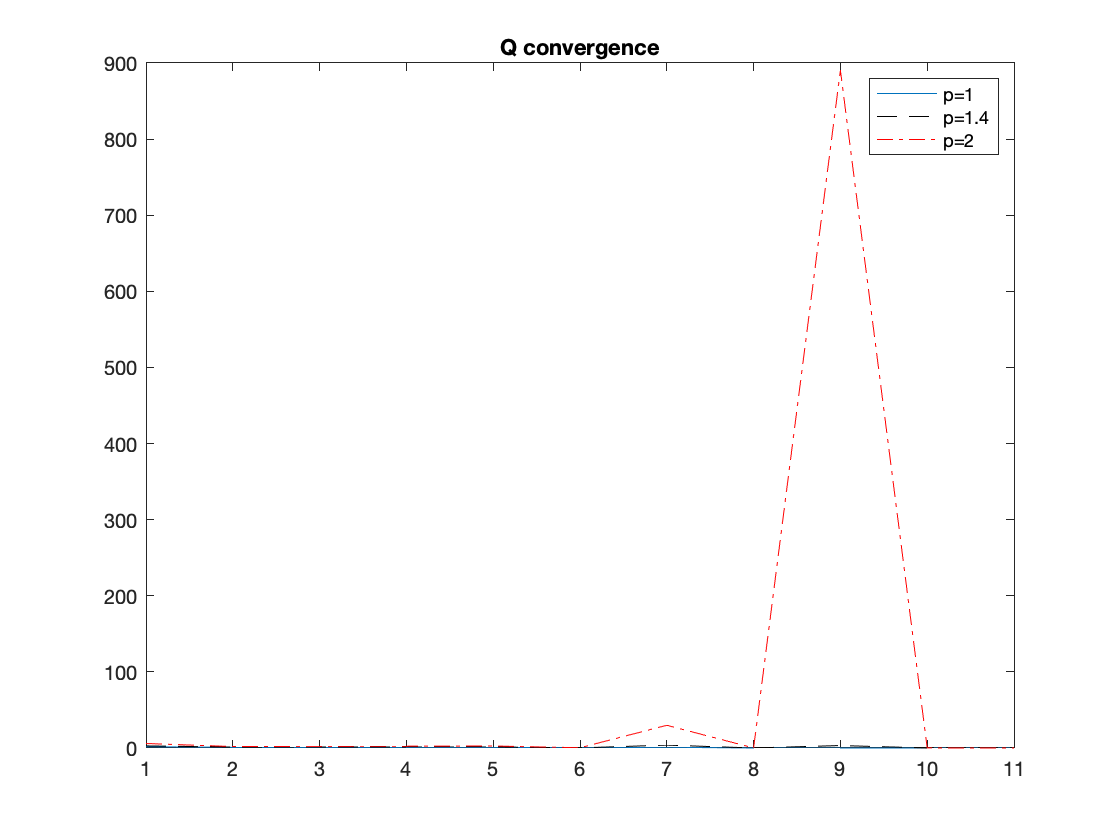

figure, plot(rs1); hold on; plot(rss,'k--'); plot(rs2,'r-.'); title('Q convergence'); legend('p=1',['p=' num2str(ps)],'p=2')